%%%% https://www.neuraldesigner.com/
%%%% EXAMPLE https://www.neuraldesigner.com/learning/examples/telecommunications-churn#DataSet
clear all

%%%% folder path 
dirName = 'C:\Users\rob\OneDrive - Hogeschool Rotterdam\WORKSHOPS\AI_TOEPASSER\RECOURCES\NEURAL_DESIGNER\DATA_SET';

%%dirName = 'C:\Users\PROMET01\OneDrive - Hogeschool Rotterdam\WORKSHOPS\AI_TOEPASSER\RECOURCES\NEURAL_DESIGNER\DATA_SET';

%dirName = 'C:\Users\PROMET01\OneDrive - Hogeschool Rotterdam\WORKSHOPS\AI_TOEPASSER\RECOURCES\NEURAL_DESIGNER\DATA_SET';
cd(dirName) %make it the current directory

files = dir(fullfile(dirName,'*.csv') );   %# list all *.xyz files
files = {files.name}';                      %'# file names 


numfiles = files;
for k=1:length(numfiles)
  numfiles{k}=[num2str(k), ' ',numfiles{k}];
end

disp(numfiles)

    {'1 blood_donation.csv'            }
    {'2 bodyfat.csv'                   }
    {'3 breast_cancer.csv'             }
    {'4 combined_cycle_power_plant.csv'}
    {'5 concrete_properties.csv'       }
    {'6 creditcard-fraud.csv'          }
    {'7 fault_detection.csv'           }
    {'8 iris_flowers.csv'              }
    {'9 power-plant-gas-emissions.csv' }
    {'10 telecommunications_churn.csv' }
    {'11 tree_wilt.csv'                }
    {'12 yacht_hydrodynamics.csv'      }



clear k,numfiles

numfiles = 12×1 cell array
    {'1 blood_donation.csv'            }
    {'2 bodyfat.csv'                   }
    {'3 breast_cancer.csv'             }
    {'4 combined_cycle_power_plant.csv'}
    {'5 concrete_properties.csv'       }
    {'6 creditcard-fraud.csv'          }
    {'7 fault_detection.csv'           }
    {'8 iris_flowers.csv'              }
    {'9 power-plant-gas-emissions.csv' }
    {'10 telecommunications_churn.csv' }
    {'11 tree_wilt.csv'                }
    {'12 yacht_hydrodynamics.csv'      }


data = readtable(char(files(5)))

data = 425×8 table
    cement    blast_furnace_slag    fly_ash    water    superplasticizer    coarse_aggregate    fine_aggregate    compressive_strength
    ______    __________________    _______    _____    ________________    ________________    ______________    ____________________

      540               0              0         162           2.5                 1040               676                79.99        
      540               0              0         162           2.5                 1055               676                61.89        
      380              95              0         228             0                  932               594                36.45        
      266             114        

% [data tb] = rmoutliers(cdata);
% data
varnames=data.Properties.VariableNames

varnames = 1×8 cell array
    {'cement'}    {'blast_furnace_slag'}    {'fly_ash'}    {'water'}    {'superplasticizer'}    {'coarse_aggregate'}    {'fine_aggregate'}    {'compressive_strength'}


%%% CREATE TEST DATA

testdata=data(100,1:end)

testdata = 1×8 table
    cement    blast_furnace_slag    fly_ash    water    superplasticizer    coarse_aggregate    fine_aggregate    compressive_strength
    ______    __________________    _______    _____    ________________    ________________    ______________    ____________________

     356             119               0        160            9                  1061               657                   59         


%%%%%yfit = trainedModelrob.predictFcn(testdata)

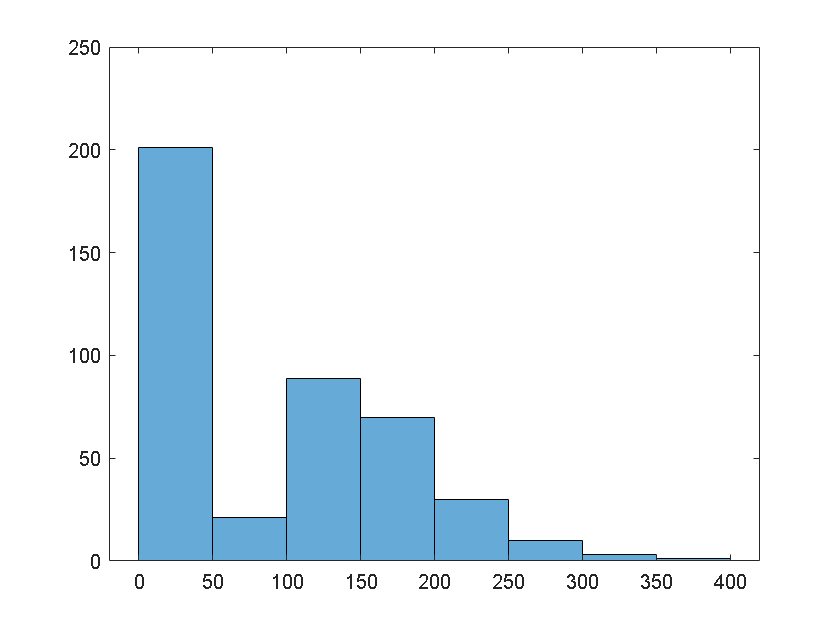

%%% CREATE histogram from NOx variable

histogram(data.(2))

x=1:width(data)-1;
y=data{1:end,2};

% z=data{1:end,2};
% [y,tb] = rmoutliers(z);  %remove outliers


ncount=hist(y)

ncount =    197     8    29    56    60    48    16     5     4     2


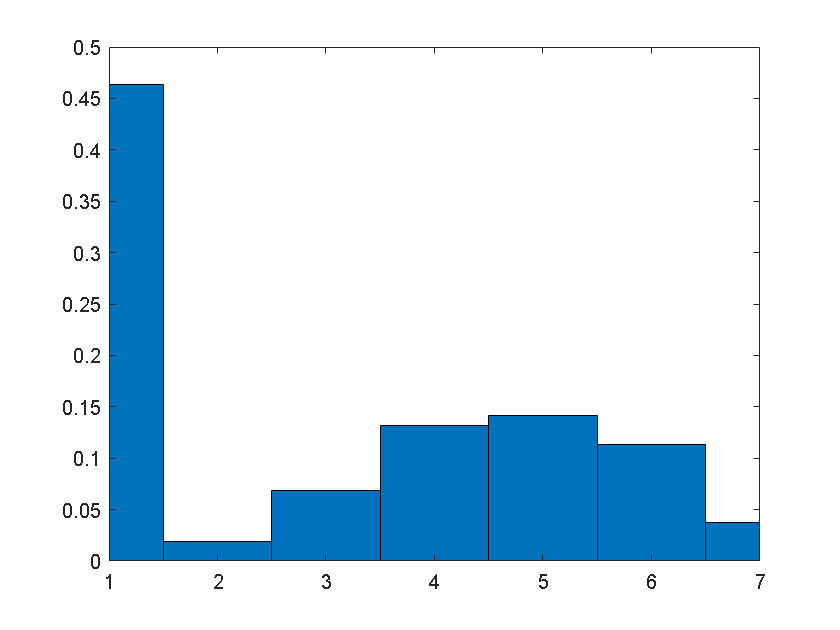

relativefreq = ncount/length(y);
numIntervals =  12;
intervalWidth = (max(y) - min(y))/numIntervals;
bar(relativefreq,1)
xlim([min(x) max(x)])
set(gca, 'xtick', x)

text(x,relativefreq,num2str((relativefreq*100)','%0.2f'),'vert','bottom','horiz','center'); 

Error using text
X and Y must be the same length

box off

format short
[r, p]= corrcoef(data.(1),data.(width(data)))

r =     1.0000    0.6661
    0.6661    1.0000


p =     1.0000    0.0000
    0.0000    1.0000


measurement_vars =  data{1:end,1:width(data)-2}

measurement_vars = 1.0e+03 *

    0.5400         0         0    0.1620    0.0025    1.0400
    0.5400         0         0    0.1620    0.0025    1.0550
    0.3800    0.0950         0    0.2280         0    0.9320
    0.2660    0.1140         0    0.2280         0    0.9320
    0.4750         0         0    0.2280         0    0.9320
    0.1986    0.1324         0    0.1920         0    0.9784
    0.3040    0.0760         0    0.2280         0    0.9320
    0.1396    0.2094         0    0.1920         0    1.0470
    0.4275    0.0475         0    0.2280         0    0.9320
    0.2375    0.2375         0    0.2280         0    0.9320


target_var = data.(width(data))

target_var =    79.9900
   61.8900
   36.4500
   45.8500
   39.2900
   28.0200
   47.8100
   28.2400
   37.4300
   30.0800


cdata = corr(measurement_vars,target_var,'rows','complete')

cdata =     0.6661
    0.1414
   -0.2694
   -0.3986
    0.2134
   -0.1203


labels = categorical( regexprep(varnames(1:end-2), '_', ' ') )

labels = 1×6 categorical array
     cement      blast furnace slag      fly ash      water      superplasticizer      coarse aggregate 


%[a b ] = sort(labels,'ascend')
[a b] = sort(abs(cdata))

a =     0.1203
    0.1414
    0.2134
    0.2694
    0.3986
    0.6661


b =      6
     2
     5
     3
     4
     1


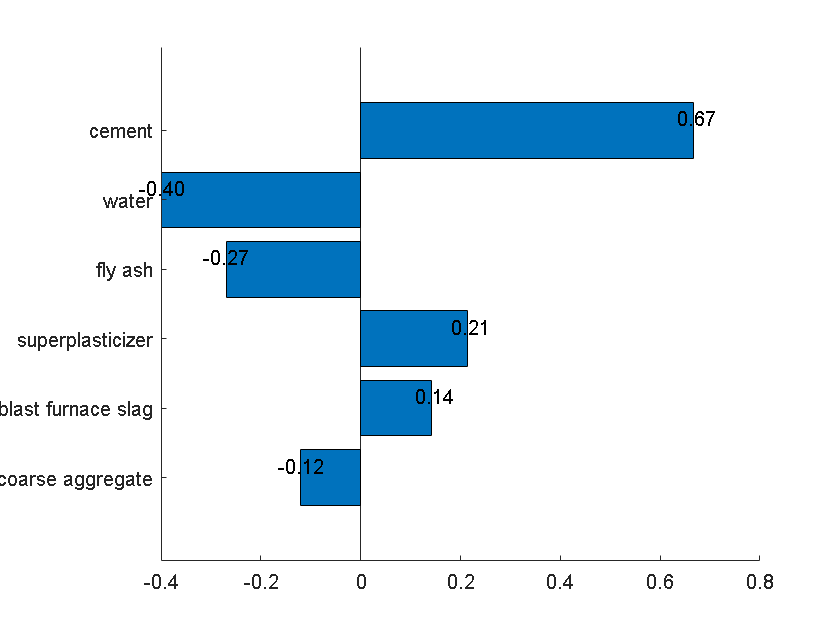

barh(cdata(b))
set(gca, 'YTickLabel', labels(b))
xx=1:6;
yy=cdata(b);
text(yy,xx,num2str((yy),'%0.2f'),'horiz','center','vert','bottom')
box off

Here are the steps for exporting a model to the MATLAB® workspace:

In the app, select the model you want to export in the Models pane.

On the Regression Learner tab, in the Export section, click one of the export options:

To include the data used for training the model, click Export Model and select Export Model. This option exports the trained model to the workspace as a structure containing a regression object, such as RegressionTree. The model object includes the training data when possible. Note that some models, such as kernel approximation models, never store training data.

To exclude the training data, click Export Model and select Export Compact Model. This option exports the model with unnecessary data removed. That is, the exported structure contains a regression object that, when possible, does not include the training data. You can still use the model for making predictions on new data.

In the Export Model dialog box, check the name of your exported variable, and edit it if you want. Then, click OK. The default name for your exported model, trainedModel, increments every time you export to avoid overwriting your models (for example, trainedModel1).

The new variable (for example, trainedModel) appears in your workspace.

The app displays information about the exported model in the command window. Read the message to learn how to make predictions with new data.

%%%% HOW TO USE MODEL TO PREDICT
% On the Regression Learner tab, in the Export section, click one of the export option
% ====> Export Compact Mode

% read in test Data as a Cell labels + values
 testdata=data(100,1:end-1);

 %%%  predicted vs actual
 yfit = trainedModelZ.predictFcn(testdata)  % predict

Unable to resolve the name 'trainedModelZ.predictFcn'.

 data{100,end:end}                            % actual